% Main 6-DOF Aircraft Simulation
% Clear workspace
clear; clc; close all;

fprintf('Starting 6-DOF Aircraft Simulation...\n');

Starting 6-DOF Aircraft Simulation...


## Aircraft Parameters

aircraft.m = 1200;                    % Mass (kg)
aircraft.Ixx = 2000;                  % Roll inertia (kg*m^2)
aircraft.Iyy = 4000;                  % Pitch inertia (kg*m^2)
aircraft.Izz = 5000;                  % Yaw inertia (kg*m^2)
aircraft.Ixz = 100;                   % Cross product inertia (kg*m^2)

% Inertia tensor
aircraft.I = [aircraft.Ixx, 0, -aircraft.Ixz;
    0, aircraft.Iyy, 0;
    -aircraft.Ixz, 0, aircraft.Izz];
aircraft.invI = inv(aircraft.I);

aircraft.g = 9.81;                    % Gravity (m/s^2)
aircraft.rho = 1.225;                 % Air density (kg/m^3)

% Geometric parameters
aircraft.S = 20;                      % Wing area (m^2)
aircraft.c = 2;                       % Mean aerodynamic chord (m)
aircraft.b = 10;                      % Wingspan (m)

## Initial Conditions

State vector: [u, v, w, p, q, r, phi, theta, psi, x, y, z]

y0 = [100;        % u - forward velocity (m/s)
    0;         % v - lateral velocity (m/s)
    0;         % w - vertical velocity (m/s)
    0;         % p - roll rate (rad/s)
    0;         % q - pitch rate (rad/s)
    0;         % r - yaw rate (rad/s)
    0;         % phi - roll angle (rad)
    0.1;       % theta - pitch angle (rad)
    0;         % psi - yaw angle (rad)
    0;         % x - north position (m)
    0;         % y - east position (m)
    1000];     % z - altitude (m)

## Simulation Time

tspan = [0 30];   % Simulate for 30 seconds

## Run Simulation

fprintf('Running simulation...\n');

Running simulation...


options = odeset('RelTol', 1e-6, 'AbsTol', 1e-9);
[t, y] = ode45(@(t,y) aircraft_6dof(t, y, aircraft), tspan, y0, options);

## Plot Results

Plotting results...


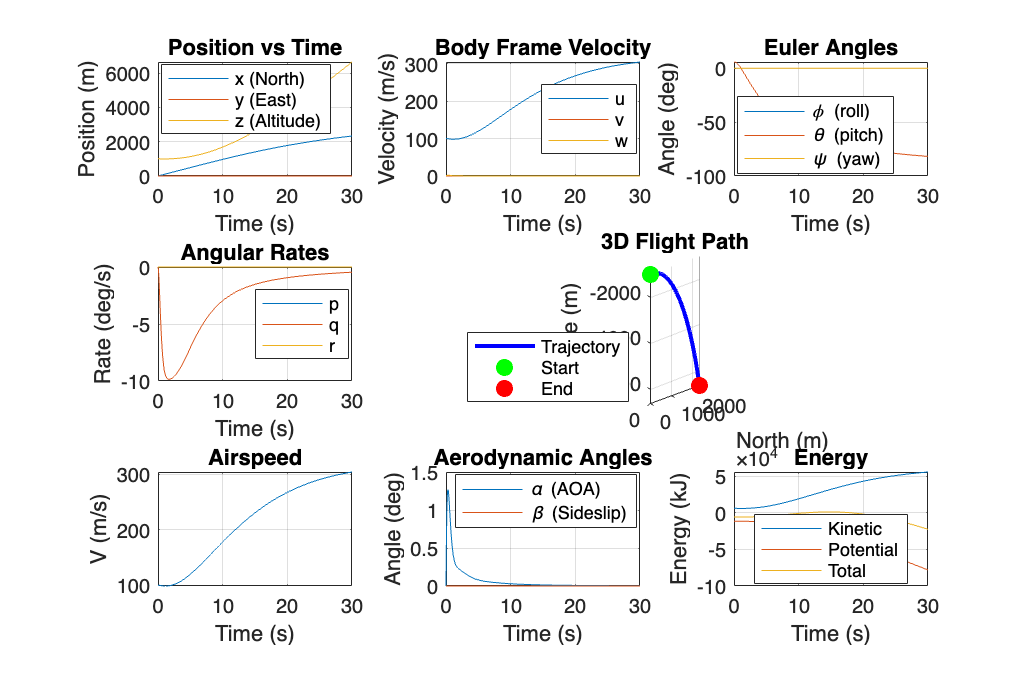


=== SIMULATION RESULTS ===
Final Position: [2330.1, 0.0, 6643.1] m
Final Velocity: [304.1, 0.0, 0.0] m/s
Final Euler Angles: [0.0, -81.8, 0.0] deg
Final Airspeed: 304.1 m/s


plot_results(t, y, aircraft);


fprintf('Simulation completed!\n');

Simulation completed!



% =========================================================================
% REQUIRED FUNCTIONS (ADD THESE AT THE END OF YOUR SCRIPT)
% =========================================================================

function dydt = aircraft_6dof(t, y, ac)
% 6-DOF Aircraft Equations of Motion

% Extract state variables
u = y(1); v = y(2); w = y(3);           % Body frame velocities
p = y(4); q = y(5); r = y(6);           % Body frame angular rates
phi = y(7); theta = y(8); psi = y(9);   % Euler angles
x = y(10); y_pos = y(11); z = y(12);    % Inertial positions

% Calculate forces and moments
[F, M] = forces_moments(t, y, ac);

% --- LINEAR MOTION EQUATIONS (Body frame) ---
dudt = F(1)/ac.m - q*w + r*v - ac.g*sin(theta);
dvdt = F(2)/ac.m - r*u + p*w + ac.g*cos(theta)*sin(phi);
dwdt = F(3)/ac.m - p*v + q*u + ac.g*cos(theta)*cos(phi);

% --- ANGULAR MOTION EQUATIONS (Body frame) ---
omega = [p; q; r];
domega = ac.invI * (M - cross(omega, ac.I * omega));
dpdt = domega(1);
dqdt = domega(2);
drdt = domega(3);

% --- KINEMATIC EQUATIONS (Euler angles) ---
dphidt = p + q*sin(phi)*tan(theta) + r*cos(phi)*tan(theta);
dthetadt = q*cos(phi) - r*sin(phi);
dpsidt = q*sin(phi)/cos(theta) + r*cos(phi)/cos(theta);

% --- NAVIGATION EQUATIONS ---
% Rotation matrix from body to inertial frame
R_bi = [cos(theta)*cos(psi), sin(phi)*sin(theta)*cos(psi)-cos(phi)*sin(psi), cos(phi)*sin(theta)*cos(psi)+sin(phi)*sin(psi);
    cos(theta)*sin(psi), sin(phi)*sin(theta)*sin(psi)+cos(phi)*cos(psi), cos(phi)*sin(theta)*sin(psi)-sin(phi)*cos(psi);
    -sin(theta),         sin(phi)*cos(theta),                            cos(phi)*cos(theta)];

% Transform velocity from body to inertial frame
vel_inertial = R_bi * [u; v; w];
dxdt = vel_inertial(1);
dydt_pos = vel_inertial(2);
dzdt = vel_inertial(3);

% Assemble derivative vector
dydt = [dudt; dvdt; dwdt; dpdt; dqdt; drdt;
    dphidt; dthetadt; dpsidt;
    dxdt; dydt_pos; dzdt];
end

function [F, M] = forces_moments(t, y, ac)
% Compute aerodynamic and propulsive forces and moments

% Extract states
u = y(1); v = y(2); w = y(3);
p = y(4); q = y(5); r = y(6);
phi = y(7); theta = y(8); psi = y(9);

% Calculate airspeed and aerodynamic angles
V = sqrt(u^2 + v^2 + w^2);

% Avoid division by zero for small velocities
if V < 0.1
    alpha = 0;
    beta = 0;
    V = 0.1;
else
    alpha = atan2(w, u);      % Angle of attack
    beta = asin(v/V);         % Sideslip angle
end

% --- AERODYNAMIC COEFFICIENTS (Simplified Model) ---

% Force coefficients
CD = 0.02 + 0.15*alpha^2;     % Drag coefficient
CL = 2*pi*alpha;              % Lift coefficient (linear)
CY = -0.5*beta;               % Side force coefficient

% Moment coefficients (stability derivatives)
Cl = -0.1*beta - 0.2*p*ac.b/(2*V) + 0.01*r*ac.b/(2*V);      % Roll moment
Cm = -0.2*alpha - 0.5*q*ac.c/(2*V);                         % Pitch moment
Cn = 0.05*beta - 0.01*p*ac.b/(2*V) - 0.1*r*ac.b/(2*V);      % Yaw moment

% Dynamic pressure
Q = 0.5 * ac.rho * V^2 * ac.S;

% --- AERODYNAMIC FORCES (Body frame) ---
F_aero = Q * [-CD;    % X-force (drag)
    CY;    % Y-force (side force)
    -CL];   % Z-force (lift)

% --- GRAVITY FORCES (Body frame) ---
F_gravity = ac.m * ac.g * [-sin(theta);
    cos(theta)*sin(phi);
    cos(theta)*cos(phi)];

% --- PROPULSIVE FORCES (Simple thrust model) ---
F_thrust = [ac.m * 1.5; 0; 0];  % Constant thrust

% --- TOTAL FORCES ---
F = F_aero + F_gravity + F_thrust;

% --- MOMENTS (Body frame) ---
M = Q * [Cl * ac.b;    % Roll moment
    Cm * ac.c;    % Pitch moment
    Cn * ac.b];   % Yaw moment
end

function plot_results(t, y, ac)
% Plot simulation results

fprintf('Plotting results...\n');

% Create figure with subplots
figure('Position', [100, 100, 1200, 800]);

% Plot 1: Position
subplot(3,3,1);
plot(t, y(:,10:12));
title('Position vs Time');
xlabel('Time (s)'); ylabel('Position (m)');
legend('x (North)', 'y (East)', 'z (Altitude)', 'Location', 'best');
grid on;

% Plot 2: Body Frame Velocity
subplot(3,3,2);
plot(t, y(:,1:3));
title('Body Frame Velocity');
xlabel('Time (s)'); ylabel('Velocity (m/s)');
legend('u', 'v', 'w', 'Location', 'best');
grid on;

% Plot 3: Euler Angles
subplot(3,3,3);
plot(t, rad2deg(y(:,7:9)));
title('Euler Angles');
xlabel('Time (s)'); ylabel('Angle (deg)');
legend('\phi (roll)', '\theta (pitch)', '\psi (yaw)', 'Location', 'best');
grid on;

% Plot 4: Angular Rates
subplot(3,3,4);
plot(t, rad2deg(y(:,4:6)));
title('Angular Rates');
xlabel('Time (s)'); ylabel('Rate (deg/s)');
legend('p', 'q', 'r', 'Location', 'best');
grid on;

% Plot 5: 3D Trajectory
subplot(3,3,[5,6]);
plot3(y(:,10), y(:,11), -y(:,12), 'b-', 'LineWidth', 2);
hold on;
plot3(y(1,10), y(1,11), -y(1,12), 'go', 'MarkerSize', 8, 'MarkerFaceColor', 'g');
plot3(y(end,10), y(end,11), -y(end,12), 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r');
xlabel('North (m)'); ylabel('East (m)'); zlabel('Altitude (m)');
title('3D Flight Path');
legend('Trajectory', 'Start', 'End', 'Location', 'best');
grid on;
axis equal;

% Plot 6: Airspeed
subplot(3,3,7);
V = sqrt(y(:,1).^2 + y(:,2).^2 + y(:,3).^2);
plot(t, V);
title('Airspeed');
xlabel('Time (s)'); ylabel('V (m/s)');
grid on;

% Plot 7: Angle of Attack and Sideslip
subplot(3,3,8);
alpha = atan2(y(:,3), y(:,1));
beta = asin(y(:,2) ./ V);
plot(t, rad2deg(alpha), t, rad2deg(beta));
title('Aerodynamic Angles');
xlabel('Time (s)'); ylabel('Angle (deg)');
legend('\alpha (AOA)', '\beta (Sideslip)', 'Location', 'best');
grid on;

% Plot 8: Energy
subplot(3,3,9);
kinetic = 0.5 * ac.m * V.^2;
potential = ac.m * ac.g * (-y(:,12));
total_energy = kinetic + potential;
plot(t, kinetic/1000, t, potential/1000, t, total_energy/1000);
title('Energy');
xlabel('Time (s)'); ylabel('Energy (kJ)');
legend('Kinetic', 'Potential', 'Total', 'Location', 'best');
grid on;

% Display final values
fprintf('\n=== SIMULATION RESULTS ===\n');
fprintf('Final Position: [%.1f, %.1f, %.1f] m\n', y(end,10), y(end,11), y(end,12));
fprintf('Final Velocity: [%.1f, %.1f, %.1f] m/s\n', y(end,1), y(end,2), y(end,3));
fprintf('Final Euler Angles: [%.1f, %.1f, %.1f] deg\n', ...
    rad2deg(y(end,7)), rad2deg(y(end,8)), rad2deg(y(end,9)));
fprintf('Final Airspeed: %.1f m/s\n', V(end));
end